# A CLASSIX implementation for MATLAB

## What is CLASSIX?

CLASSIX is a fast and memory-efficient clustering algorithm which produces explainable results. It exploits an initial sorting of the data points along their first principal axis to quickly assign data points to groups, followed by the merging of groups into clusters. In contrast to clustering methods like DBSCAN, CLASSIX does use any tree-based data structures to perform nearest-neighbor searches. In fact, CLASSIX's memory requirement grows only linearly in the number of data points. In contrast to the popular k-means algorithm, which is tailored to spherical clusters, CLASSIX can detect clusters of arbitrary shape. 

If you'd like to learn more about CLASSIX, here are a couple of online references:

- arXiv paper: [Fast and explainable clustering based on sorting (arxiv.org)](https://arxiv.org/abs/2202.01456)

- GitHub page: [Fast and explainable clustering based on sorting (github.com)](https://github.com/nla-group/classix)

- YouTube video: [CLASSIX - Fast and explainable clustering based on sorting - YouTube](https://www.youtube.com/watch?v=K94zgRjFEYo)

## This MATLAB implementation

The MATLAB code `classix.m` fully implements all CLASSIX features using the distance-based merging criterion. In particular, it provides full `minPts` functionality and an `explain()` function. 

Using `classix.m` straightforward. To demonstrate, let's create with an artificial data set comprised of two Gaussian blobs in 2D. We choose the CLASSIX radius parameter as `0.2` and set `minPts=10.`

clear all
close all hidden
rng('default')                  % For reproducibility
mu1 = [2 2];                    % Mean of the 1st component
sigma1 = [2 0; 0 1];            % Covariance of the 1st component
mu2 = [-4 -3];                  % Mean of the 2nd component
sigma2 = [1 0; 0 1];            % Covariance of the 2nd component
r1 = mvnrnd(mu1,sigma1,1e3);
r2 = mvnrnd(mu2,sigma2,1e3);
X = [r1; r2];
tic
[label, explain, out] = classix(X, 0.2, 10); 
toc

Elapsed time is 0.097133 seconds.


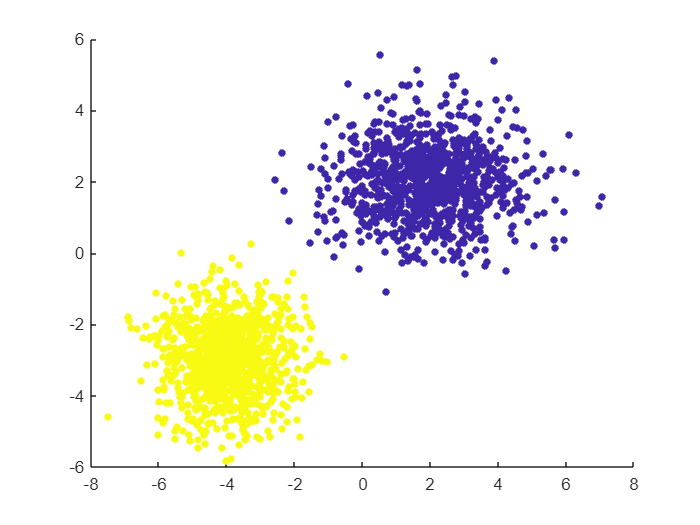

figure
scatter(X(:,1),X(:,2),20,label,"filled"); shg
hold on

`classix.m` has three output parameter, but what matters most are the first two: the vector `label` (containing the cluster label of each data point) and the `explain` function handle. Let's call `explain()` without any input parameters in order to produce CLASSIX's textual summary of the performed clustering, and also to conveniently provide us with a plot of the clusters.

A clustering of 2000 data points with 2 features was performed.
The radius parameter was set to 0.20 and MinPts was set to 10.
As the provided data was auto-scaled by a factor of 1/4.02,
points within a radius R=0.20*4.02=0.80 were grouped together.
In total, 12708 distances were computed (6.4 per data point).
This resulted in 93 groups, each with a unique starting point.
These 93 groups were subsequently merged into 2 clusters.
In order to explain the clustering of individual data points,
use explain(ind1) or explain(ind1,ind2) with indices of points.


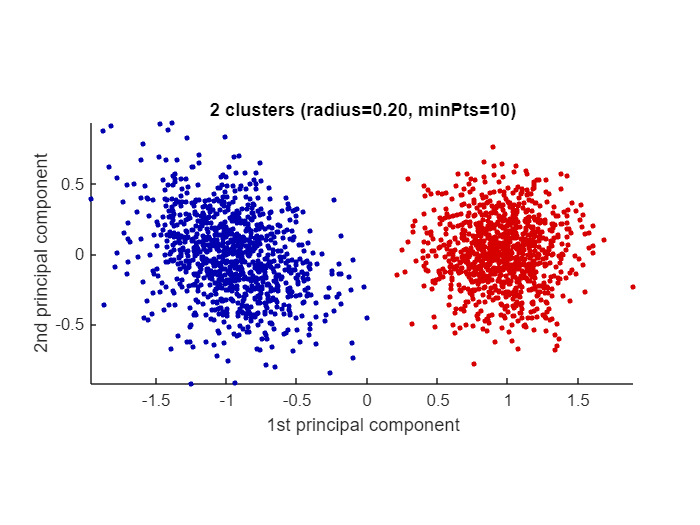

explain()

We can now explore single data points or pairs of data points in order to understand why they have been clustered together, or not. For example, let's find out why data points 100 and 800 ended up in the same cluster:

Data point 100 is in group 49, which was merged into cluster #1.
Data point 800 is in group 6, which was merged into cluster #1.
A path of overlapping groups with step size <= 1.5*R = 1.21 is:
 49 -> 44 -> 38 -> 29 -> 18 -> 12 -> 7 -> 6


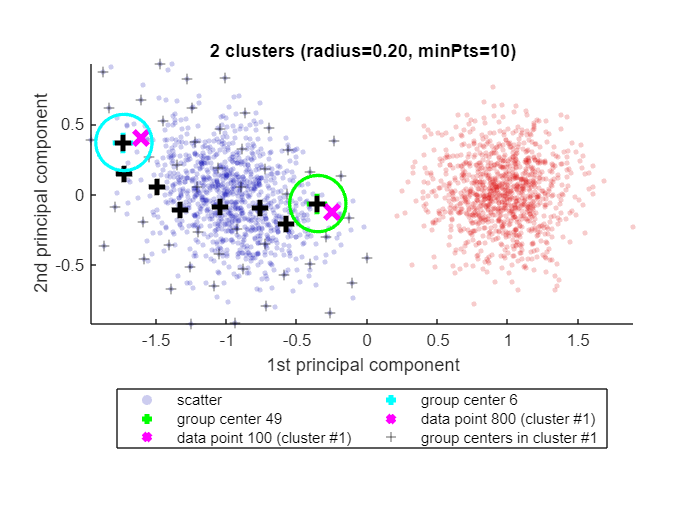

explain(100,800)

See how CLASSIX has highlighted the two data points 100 and 800 as magenta crosses (x) in the blue cluster (cluster #1). Each of these data points falls into a group (group number 49 and 6, respectively) and the group centers are shown as black pluses (`+`),with the green and cyan circles indicating the group radius. 

CLASSIX's explanation of why both points are in the same cluster is that there is a path of overlapping groups leading from group 49 to group 6, and this path is also shown with black pluses (`+`). This feature simply uses MATLAB's `shortestpath` graph function. However, note that the path is not necessarily the shortest due to the sequential nature of the group merging. It is just *some* path of data points (group centers) within the cluster that connects the groups containing the two data points in question.

## An experimental option

We have also added a new experimental option to `classix.m,` namely a fourth input parameter called `merge_tiny_groups.` This parameter is `true` by default, resulting in the original CLASSIX method. But when it is set to `false,` tiny groups with fewer than `minPts` points will be ignored in the merging phase and become stand-alone clusters first, before they are subsequently merged into a nearest bigger cluster. (That's different from the usual `minPts` criterion which affects clusters, not working on the group level.) This can sometimes avoid 'creeping' between small groups, whereby clusters get merged simply because they are touched by low density groups. With  `merge_tiny_groups` set to `false,` we can often cluster Gaussian blob data even when the blobs are visibly intersecting.

rng('default')                   
mu1 = [2 2];             
sigma1 = [2 0; 0 1];
mu2 = [-4 -3];                 
sigma2 = [1 0; 0 1];           
r1 = mvnrnd(mu1,sigma1,1e5);   % much larger number of data points!
r2 = mvnrnd(mu2,sigma2,1e5);
X = [r1; r2];
tic;
[label, explain, out] = classix(X, 0.1, 50, 0);  % note the final 0 option
toc

Elapsed time is 0.233068 seconds.


A clustering of 200000 data points with 2 features was performed.
The radius parameter was set to 0.10 and MinPts was set to 50.
As the provided data was auto-scaled by a factor of 1/4.05,
points within a radius R=0.10*4.05=0.41 were grouped together.
In total, 3664460 distances were computed (18.3 per data point).
This resulted in 635 groups, each with a unique starting point.
These 635 groups were subsequently merged into 2 clusters.
In order to explain the clustering of individual data points,
use explain(ind1) or explain(ind1,ind2) with indices of points.
Too many data points for plot. Randomly subsampled 1e5 points.


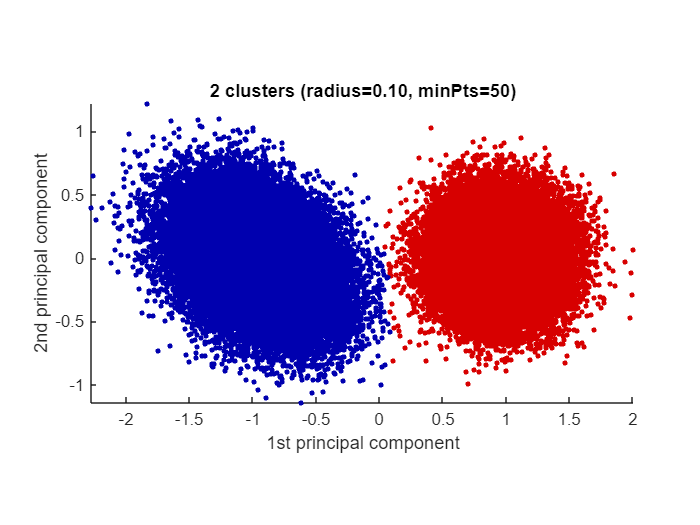

explain()

## Is `classix.m` fast?

Yes, `classix.m` has been optimized for speed and low memory consumption, and can be even faster than the original Python CLASSIX implementation. Let's test CLASSIX on a slightly larger dataset, namely the `'Phoneme'` dataset from the UCI Machine Learning Repository [3]. We're using the 'optimal' hyperparameters (radius, minPts) determined via grid search in the CLASSIX paper [1]. We measure the quality of the clustering using the adjusted Rand index.

ari = @(a,b) rand_index(double(a),double(b),'adjusted');
load Phoneme.mat
% z-normalization and parameters chosen identical to the test in
% https://github.com/nla-group/classix/blob/master/exp/run_real_world.py
data = (data - mean(data))./std(data); 

tic
[label, explain, out] = classix(data,0.445,8);
fprintf('  CLASSIX.m runtime: %5.3f seconds - classes: %d - ARI: %3.2f\n',...
    toc,length(unique(label)), ari(labels,label))

  CLASSIX.m runtime: 2.033 seconds - classes: 4 - ARI: 0.76


We can also compare to MATLAB's DBSCAN [3]:

%% MATLAB DBSCAN
tic
idx = dbscan(data,9.175,10); % Also determined by grid search. ARI should be 0.51.
fprintf('  DBSCAN   runtime: %5.3f seconds - classes: %d - ARI: %3.2f\n',...
    toc,length(unique(idx)), ari(labels,idx))

  DBSCAN   runtime: 1.164 seconds - classes: 5 - ARI: 0.51


DBSCAN doesn't seem to be able to achieve an ARI as high as CLASSIX, though of course one can never be certain if the chosen parameters are really the best possible. In any case, `classix.m` is less than a factor 2 slower than DBSCAN for this dataset, even though DBSCAN is fully implemented in C++.

Let's try the CLASSIX `explain` function one more time, now with two data points in separate clusters. 

Data point 1 is in group 1033, which was merged into cluster #1.
Data point 3 is in group 4354, which was merged into cluster #4.
There is no path of overlapping groups between 1033 and 4354.
(Note that with data having more than 2 features, the two
 group circles in the plot may appear bigger than they are.)


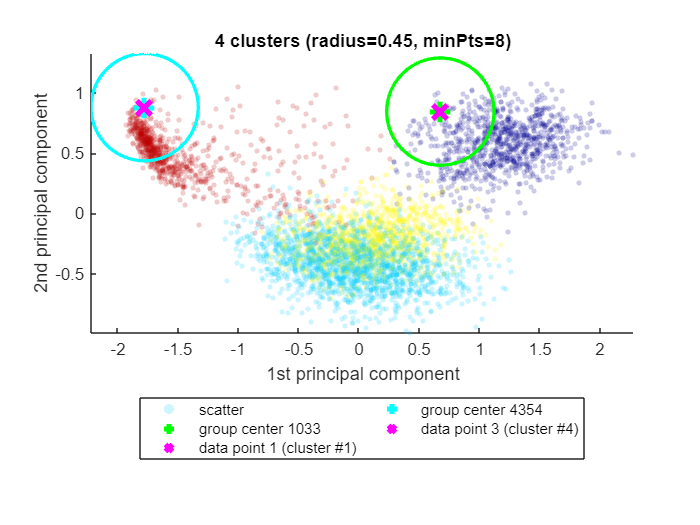

explain(1,3)

## Large number of data points and DBSCAN failure

CLASSIX becomes very powerful in particular for extremely large datasets (i.e., many data points) of not too high dimension. Here's an example with more than 2 millions data points for which CLASSIX returns reasonably looking clusterings within a single second, while DBSCAN will require several hours to complete.

load vdu_signals.mat
data = (data - mean(data))./std(data); 
% no ground truth labels for this dataset

%% classix.m - clustering more than 2M data points
tic
label = classix(data, 0.4, 6);
fprintf('  CLASSIX runtime: %5.3f seconds - classes: %d\n',...
    toc, length(unique(label)))

  CLASSIX runtime: 0.808 seconds - classes: 6


In order to run DBSCAN to completion, we downsample to 5% of the data. The hyperparameters are chosen to approximately match the clustering results.

%% MATLAB DBSCAN Attempt 3
%  We now take only 5% of the data to get DBSCAN to complete in reasonable time.
tic
idx = dbscan(data(1:20:end,:), 0.7, 6);   % subsample to 5% of data
fprintf('  DBSCAN   runtime: %6.3f seconds - classes: %d\n',...
    toc,length(unique(idx)))

  DBSCAN   runtime: 33.981 seconds - classes: 5


## Scaling test

Running DBSCAN on all 2 million data points is not feasible. Let's see how the runtime of CLASSIX and DBSCAN scales as the number of data points increases. The plot below shows that, over the range of data sizes of 10k to 100k, CLASSIX's runtime stays in the order of milliseconds, while DBSCAN's runtime grows approximately quadratically from about 0.3 second to about 30 seconds. The extrapolated DBSCAN runtime on the full dataset with approximately 2 million points would be about 5 hours.

npts = 10000:10000:100000;
t_classix = []; t_dbscan = [];
for j = 1:length(npts)
    s = round(size(data,1)/npts(j));
    dat = data(1:s:end,:);
    npts(j) = size(dat,1);
    fprintf('# of data points: %d', size(dat,1))
    tic; label = classix(dat, 0.4, 6); t_classix(j) = toc;
    fprintf('  CLASSIX runtime: %6.3f seconds - classes: %d\n', t_classix(j), length(unique(label)))
    tic; idx = dbscan(dat, 0.7, 6); t_dbscan(j) = toc;
    fprintf('  DBSCAN  runtime: %6.3f seconds - classes: %d\n', t_dbscan(j), length(unique(idx)))
end

# of data points: 9994

  CLASSIX runtime:  0.009 seconds - classes: 4  ---

  DBSCAN  runtime:  0.344 seconds - classes: 5


# of data points: 20087

  CLASSIX runtime:  0.010 seconds - classes: 4  ---

  DBSCAN  runtime:  0.986 seconds - classes: 4


# of data points: 29835

  CLASSIX runtime:  0.013 seconds - classes: 4  ---

  DBSCAN  runtime:  2.090 seconds - classes: 5


# of data points: 39780

  CLASSIX runtime:  0.017 seconds - classes: 5  ---

  DBSCAN  runtime:  3.194 seconds - classes: 6


# of data points: 49483

  CLASSIX runtime:  0.023 seconds - classes: 7  ---

  DBSCAN  runtime:  5.088 seconds - classes: 5


# of data points: 59670

  CLASSIX runtime:  0.025 seconds - classes: 5  ---

  DBSCAN  runtime:  7.341 seconds - classes: 5


# of data points: 69958

  CLASSIX runtime:  0.023 seconds - classes: 6  ---

  DBSCAN  runtime: 11.974 seconds - classes: 7


# of data points: 81152

  CLASSIX runtime:  0.052 seconds - classes: 7  ---

  DBSCAN  runtime: 17.149 seconds - classes: 6


# of data points: 88208

  CLASSIX runtime:  0.049 seconds - classes: 9  ---

  DBSCAN  runtime: 22.046 seconds - classes: 6


# of data points: 101439

  CLASSIX runtime:  0.052 seconds - classes: 8  ---

  DBSCAN  runtime: 30.792 seconds - classes: 5


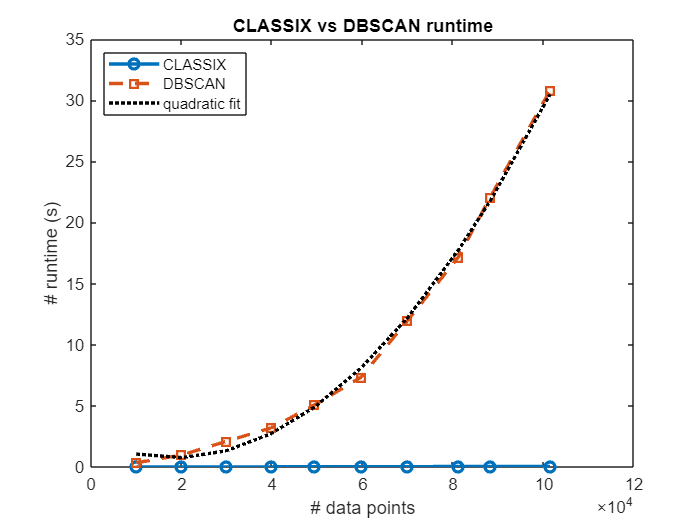

figure
plot(npts,t_classix,'-o','LineWidth',2)
hold on
plot(npts,t_dbscan,'--s','LineWidth',2)
p = polyfit(npts, t_dbscan, 2);
plot(npts,polyval(p, npts),'k:','LineWidth',2)
legend('CLASSIX','DBSCAN','quadratic fit', 'Location','northwest')
xlabel('# data points'); ylabel('# runtime (s)'); title('CLASSIX vs DBSCAN runtime')

fprintf('Extrapolated DBSCAN runtime for all %d datapoints: %3.1f hours.',size(data,1),polyval(p,size(data,1))/3600)

Extrapolated DBSCAN runtime for all 2028780 datapoints: 4.8 hours.

## CLASSIX plotting for large datasets

Scatter plotting of such large data sets can be very slow, so the `explain()` function automatically subsamples 100k data points of this data set for the visualization. The text output of `explain()` contains a statement about that.

tic
[label, explain, out] = classix(data, 0.4, 6);
fprintf('  CLASSIX2 runtime: %5.3f seconds - classes: %d\n',...
    toc,length(unique(label)))

  CLASSIX2 runtime: 0.816 seconds - classes: 6


A clustering of 2028780 data points with 2 features was performed.
The radius parameter was set to 0.40 and MinPts was set to 6.
As the provided data was auto-scaled by a factor of 1/0.92,
points within a radius R=0.40*0.92=0.37 were grouped together.
In total, 10833203 distances were computed (5.3 per data point).
This resulted in 100 groups, each with a unique starting point.
These 100 groups were subsequently merged into 6 clusters.
In order to explain the clustering of individual data points,
use explain(ind1) or explain(ind1,ind2) with indices of points.
Too many data points for plot. Randomly subsampled 1e5 points.


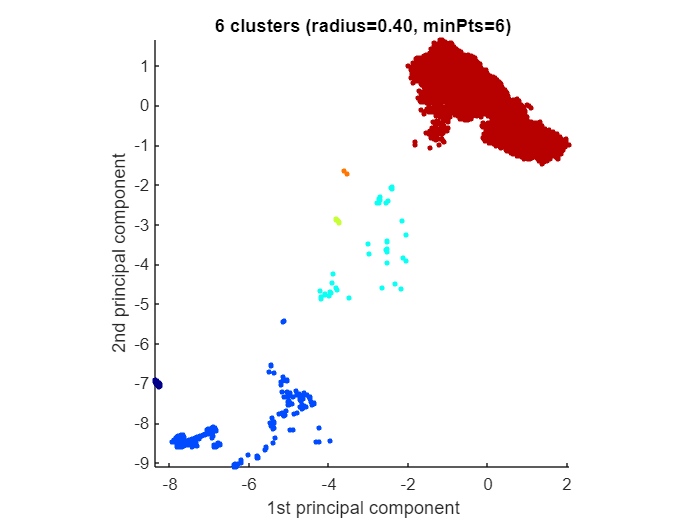

explain()

## References

[1] C. Chen and S. Güttel. *Fast and explainable clustering based on sorting.* arXiv: [https://arxiv.org/abs/2202.01456](https://arxiv.org/abs/2202.01456), 2022.

[2] D. Dua and C. Graff. *UCI machine learning repository.* URL: [http://archive.ics.uci.edu/ml,](http://archive.ics.uci.edu/ml,) 2017.

[3] M. Ester, M., H.-P. Kriegel, J. Sander, and X. Xiaowei. “A density-based algorithm for discovering clusters in large spatial databases with noise.” In *Proceedings of the Second International Conference on Knowledge Discovery in Databases and Data Mining*, 226-231. Portland, OR: AAAI Press, 1996.